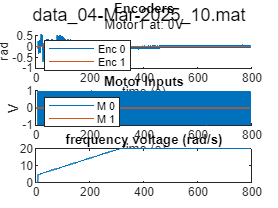

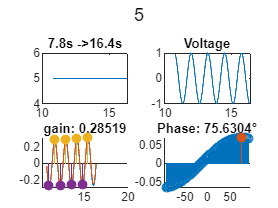

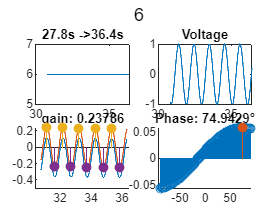

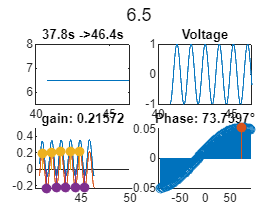

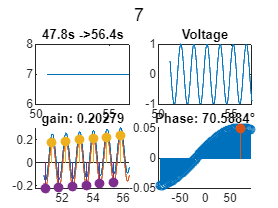

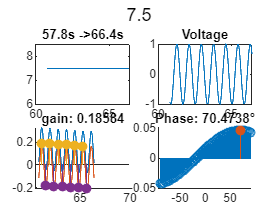

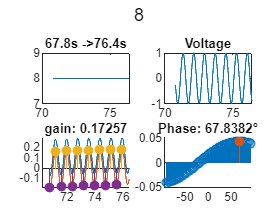

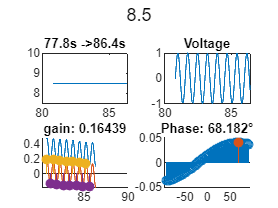

clear all;
filelist = ["data_04-Mar-2025_10.mat", 
"data_21-Mar-2025_10 motor0 19 to 31 rads.mat",
"data_21-Mar-2025_20 motor0 1v.mat",
"data_21-Mar-2025_20 motor0 31 to 40 rads 1.5v.mat"];
do_plots = true; 
% tableofData = readmatrix("lab3/data/motor0/lab2_expm0.xls");
tableofData = [];
% good : 1 4 5
% exp_id = 5;
for exp_id = 1:4
    file = "lab3/data/motor0/" + filelist(exp_id);
    load(file,"data");
    if do_plots
        smartPlotEncVoltage(data,filelist(exp_id),false);
    end
    
    fs=500;
    ts = 1/fs;
    
    motorID = 0;
    % 
    % voltages_A = [1 1 1 1.5];
    % voltage_A = voltages_A(exp_id);
    time = data(1,:);
    y = data(2+motorID,:)*pi/2048;
    u = data(4+motorID,:);
    % sweepanalysis assumes that the u has Amplitude 1
    om = data(6,:);
    
    
    slices = sliceTimeSeries(time,om);
    
    
    % wrong_exp = [ 0 5.5 13 17.5 18 20];
    
    maskOpts = detectImportOptions("lab3/data/motor0/experiment_mask_"+exp_id+".csv");
    mask = readtable("lab3/data/motor0/experiment_mask_"+exp_id+".csv",maskOpts);
    
    
    % for i = 2:2
    for i = 1:size(slices,2)
        omega = slices{i}.f;
        % k = find(wrong_exp==omega);
    if mask.enable(i) % it's one of the wrong experiments
        focus = slices{i};
    
        t_start_idx = time2index(focus.t_start+mask.t_start(i));
        t_end_idx = time2index(focus.t_end-mask.t_end(i));
       
    
        t_focus= time(t_start_idx:t_end_idx);
        om_focus= om(t_start_idx:t_end_idx);
        y_focus= y(t_start_idx:t_end_idx);
        u_focus= u(t_start_idx:t_end_idx);
        
        if do_plots
            figure
            subplot(2,2,1)
                plot(t_focus,om_focus)
                title(focus.t_start + "s ->" + focus.t_end + "s")
            subplot(2,2,2)
                plot(t_focus,u_focus)
                title("Voltage")
            subplot(2,2,[3 4])
        end
         [phase, gain, phase_del] = NewSweepAnalysis(t_focus,u_focus, y_focus, omega, do_plots);
        slices{i}.phase = phase;
        slices{i}.gain = gain;
        slices{i}.phase_del = phase_del;
    else
        slices{i}.phase = NaN;
        slices{i}.gain = NaN;
        slices{i}.phase_del = NaN;
    end
    end
    
    [freqs,phases, gains, phase_dels] = flatten(slices);
    
    % gains = gains/voltage_A;
    if do_plots
        figure
        sgtitle("Bode plot exp:" + exp_id)
        subplot(3,1,1)
        scatter(freqs,gains)
        yscale("log")
        xscale("log")
        title("Gain")
        xlabel("rad/s")
        ylabel("dB")
        
        subplot(3,1,2)
        scatter(freqs,rad2deg(phases))
        xscale("log")
        % ylim([0 90])
        title("Phase from Cross Corr")
        xlabel("rad/s")
        ylabel("deg")
        
        
        subplot(3,1,3)
        scatter(freqs,rad2deg(phase_dels))
        xscale("log")
        % ylim([0 90])
        title("Phasefrom Delay")
        xlabel("rad/s")
        ylabel("deg")
    end
    %
    % Save file
    tableofData = [tableofData ; [freqs; phases; gains]' ];


end



   
writematrix(tableofData, "lab3/data/motor0/expm0", FileType="spreadsheet",WriteMode="overwritesheet")



## Curve Fitter

% PHASE
omegas = tableofData(:,1);
phases = tableofData(:,2);
gains = tableofData(:,3);


weights = 1./(omegas.^2);

[xData, yData, weights_1] = prepareCurveData( omegas, phases, weights );


% Set up fittype and options.
ft = fittype( 'pi/2-atan(omega/p)', 'independent', 'omega', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.171186687811562;
opts.Weights = weights_1;

% Fit model to data.
[fitresult, gof, outputFit] = fit( xData, yData, ft, opts );

% % Plot fit with data.
% figure( 'Name', 'phase fit motor 1' );
% h = plot( fitresult, xData, yData, 'predobs', 0.99 );
% legend( h, 'phases vs. omegas with weights', 'phase fit motor 1', 'Lower bounds (phase fit motor 1)', 'Upper bounds (phase fit motor 1)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% % Label axes
% xlabel( 'omegas', 'Interpreter', 'none' );
% ylabel( 'phases', 'Interpreter', 'none' );
% grid on

s_omegas = sort(omegas);
fitBodePh = rad2deg(pi/2 - atan(s_omegas./fitresult.p));

% Gain

%% Fit: 'Gain Motor 1'.
[xDataG, yDataG, weights_g] = prepareCurveData( omegas, gains , weights );


% Set up fittype and options.
ftG = fittype( 'k/(omega*sqrt(omega^2+24.9218^2))', 'independent', 'omega', 'dependent', 'y' );
optsG = fitoptions( 'Method', 'NonlinearLeastSquares' );
optsG.Display = 'Off';
optsG.StartPoint = 0.959291425205444;
optsG.Weights = weights_g;

% Fit model to data.
[fitresultG, gofG, outputFitG] = fit( xDataG, yDataG, ftG, optsG );
mu = fitresultG.k/fitresult.p;

% % Plot fit with data.
% figure( 'Name', 'Gain Motor 1' );
% hG = plot( fitresultG, xDataG, yDataG, 'predobs', 0.99 );
% legend( hG, 'gains vs. omegas', 'Gain Motor 1', 'Lower bounds (Gain Motor 1)', 'Upper bounds (Gain Motor 1)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% % Label axes
% xlabel( 'omegas', 'Interpreter', 'none' );
% ylabel( 'gains', 'Interpreter', 'none' );
% grid on




## Bode Full Range

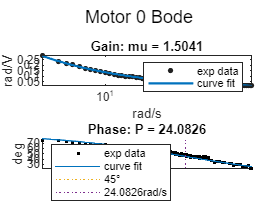

figure
subplot(2,1,1)
sgtitle("Motor 0 Bode")
% scatter(omegas,gains)
plot( fitresultG, xDataG, yDataG, 'predobs', 0.99 );
ylim([min(gains) max(gains)])
legend(["exp data","curve fit"])
title("Gain: mu = " + mu)
xscale("log")
% yscale("log")
xlabel("rad/s")
ylabel("rad/V")


subplot(2,1,2)
hold on
scatter(omegas,rad2deg(phases),"k.")
plot(s_omegas,fitBodePh,'Color',[0, 114, 189]/255)
% plot( fitresult, xData, rad2deg(yData), 'predobs', 0.99 );
plot([min(omegas) max(omegas)],[45 45],":")
plot([fitresult.p fitresult.p],[min(rad2deg(phases)) max(rad2deg(phases))],":")

legend(["exp data","curve fit" , "45°",  fitresult.p + "rad/s"],'Location','southwest')
hold off
title("Phase: P = " + fitresult.p)
ylabel("deg")
xlabel("rad/s")
xscale("log")

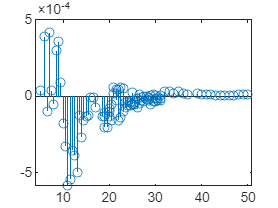

% plot( fitresult, xData, yData, 'residuals' );
% plot( fitresultG, xDataG, yDataG, 'residuals' );
figure
stem(xDataG,outputFitG.residuals)

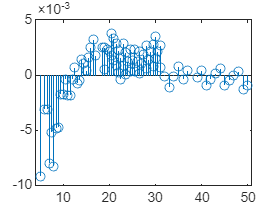

stem(xData,outputFit.residuals)

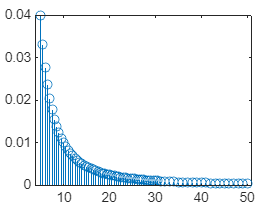


stem(omegas,weights)

function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end